%Kai Brown and Kevin Pogrund
%BRWKAI001     PGRKEV001

% Question 1
C = 37;
F = (9*C)/5 +32

F = 98.6000

% Question 2
N = [1 2 3 4 5];
a2 = 2.*N

a2 =      2     4     6     8    10


b2 = N./2

b2 =     0.5000    1.0000    1.5000    2.0000    2.5000


c2 = 1./N

c2 =     1.0000    0.5000    0.3333    0.2500    0.2000


d2=1./(N.^2)

d2 =     1.0000    0.2500    0.1111    0.0625    0.0400


%Question 3
q3 = 0;
for i = 1:1000
    q3 = q3 + 1/i*(-1)^(i-1);%the -1 is to alternate the symbol
end
q3

q3 = 0.6926

log(2)%pretty close

ans = 0.6931

%Quesion 4
xn4 = 1;
for i = 1:100
    if(rem(i+1,10)==0)
        xn4 = (10*xn4)/i%show every 10
    else
        xn4 = (10*xn4)/i;%don't show
    end
end

xn4 = 2.7557e+03

xn4 = 82.2064

xn4 = 0.0113

xn4 = 4.9025e-08

xn4 = 1.6440e-14

xn4 = 7.2107e-22

xn4 = 5.8438e-30

xn4 = 1.1178e-38

xn4 = 6.0577e-48

xn4 = 1.0715e-57

%Question 5
syms x;
signal5 = piecewise(sin(x)>0, sin(x), 0)%piecewise

$$signal5 = \left\{ \begin{array}{cl} \sin\left(x\right) & \text{ if }0<\sin\left(x\right)\\ 0 & \mathrm{otherwise} \end{array}\right.$$

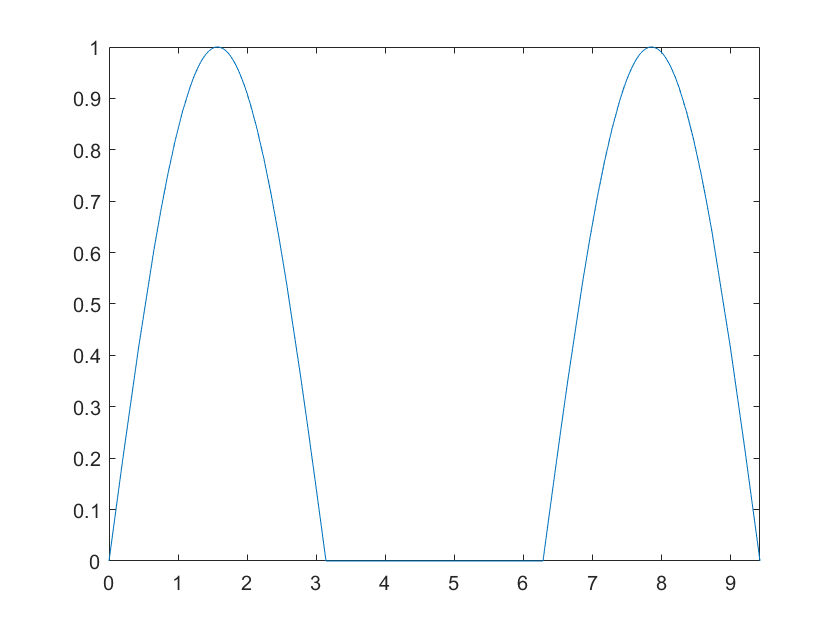

figure()
fplot(signal5,[0, 3*pi])%print in a range

%Question 6
roll = ceil(6*rand(1, 20));%Select 1-6 randomly
prob20 = nnz(roll==6)/20

prob20 = 0.3000


roll = ceil(6*rand(1, 1000));
prob1000 = nnz(roll==6)/1000

prob1000 = 0.1730

1/6

ans = 0.1667

%Question 7
b = [1:7; 9:-2:-3; 2.^[2:8]]

b =      1     2     3     4     5     6     7
     9     7     5     3     1    -1    -3
     4     8    16    32    64   128   256


a7 = b(:,5)+b(:,7)

a7 =     12
    -2
   320


b7 = b(3,:)

b7 =      4     8    16    32    64   128   256


c7=b;
temp = c7(2,:);
c7(2,:)=c7(3,:);
c7(3,:) = temp;
c7

c7 =      1     2     3     4     5     6     7
     4     8    16    32    64   128   256
     9     7     5     3     1    -1    -3


%Question 8
v1 = [1 2 3 4 5];
v2 = [1;1;1;1;1];
a8 = v1.*v2

a8 =      1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5
     1     2     3     4     5


v3 = [0;1;2;3;4];
v4 = [1,1,1];
b8 = v3.*v4

b8 =      0     0     0
     1     1     1
     2     2     2
     3     3     3
     4     4     4


%Question 9
vx = 50:0.5:100; 
vy = 100:200;
%a)
misses = zeros(length(vx)*length(vy),3);%create empty nxm x3 matrix

index = 1;
for i = 1:length(vx)%calculate miss distance for all values of vx and vy in the range
    for j = 1:length(vy)
        missedBy = cannonBall(1000, 1250, 10, vx(i), vy(j));
        misses(index,:) = [vx(i),vy(j), missedBy];
        index = index +1;
    end
end
misses %display the matrix

misses =    50.0000  100.0000  893.4989
   50.0000  101.0000  885.2289
   50.0000  102.0000  876.9950
   50.0000  103.0000  868.7982
   50.0000  104.0000  860.6394
   50.0000  105.0000  852.5199
   50.0000  106.0000  844.4408
   50.0000  107.0000  836.4032
   50.0000  108.0000  828.4083
   50.0000  109.0000  820.4573


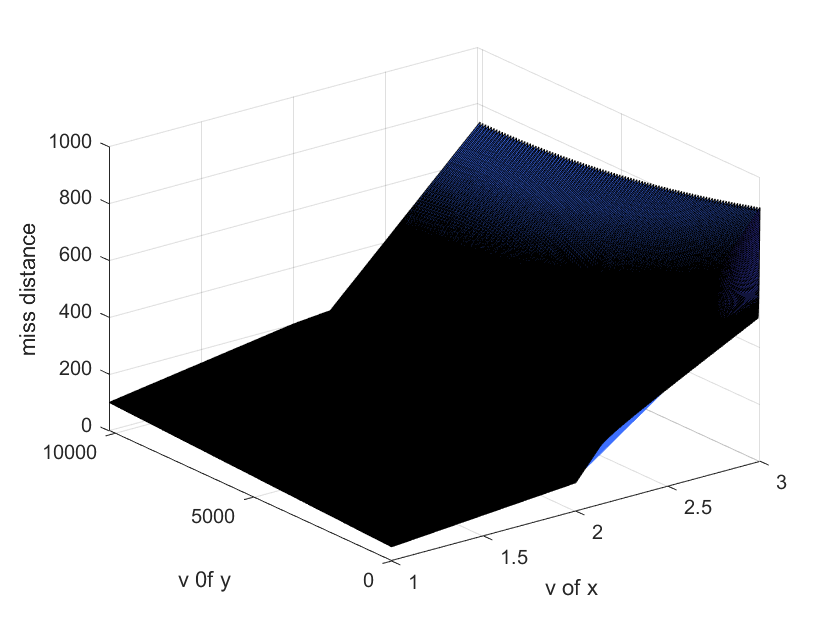


%c)
[X, Y] = meshgrid(vx, vy);
Z = cannonBall(1000, 1250, 10, X, Y);

figure()
surf(misses);
xlabel("v of x");
ylabel("v 0f y");
zlabel("miss distance");


%d)
minMissDistance = min(misses(:,3))

minMissDistance = 0.5000

indMin = find(misses(:,3)==minMissDistance);
Vx = misses(indMin, 1)

Vx = 100

Vy = misses(indMin, 2)

Vy = 174

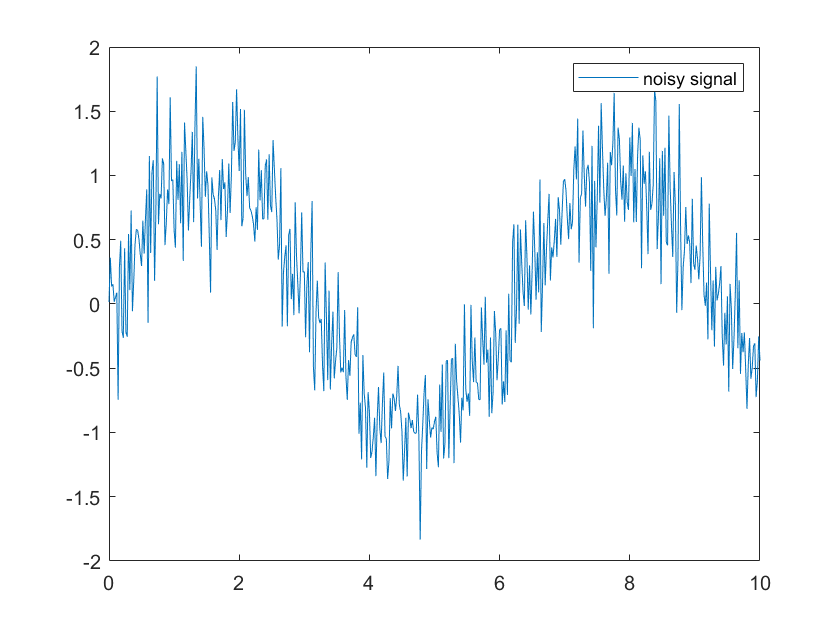

%Question 10
t10 = 0:0.02:10;
x10 = sin(t10);
signal10 = awgn(x10,10);%add white noise with variance of 1
%a)
figure()
plot(t10, signal10)
%b)

legend('noisy signal')

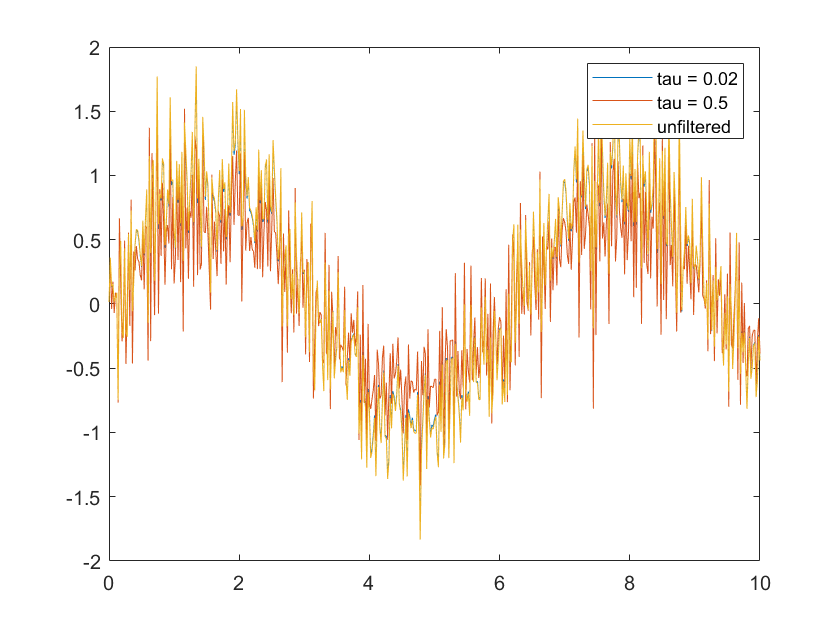

figure()
filt1 = filter(1, [1 0.02], signal10);%tau = 0.02
filt2 = filter(1, [1 0.5], signal10);%tau = 0.5
filt3 = filter(1, [1 1], signal10);%tau = 1
plot(t10, filt1)
hold on
plot(t10, filt2)
plot(t10, signal10)
% plot(t10, filt3)
legend('tau = 0.02', 'tau = 0.5', 'unfiltered', 'tau = 1')

%Question 11
file = uiimport('EEE4119F - prac 1 - data.csv');

time = ones(length(GndSpeed),1); %length of vector from csv file

Unrecognized function or variable 'GndSpeed'.

for i = 1:length(GndSpeed)
    time(i,:) = 0.01*i; %10Hz
end
figure()
%a)
plot(time, GndSpeed)
xlabel('time(s)')
ylabel('GndSpeed (m/s)')

%b
[M, I] = max(GndSpeed);
topSpeed = M
timeOfMax = time(I,1)

%c
acc = zeros(timeOfMax*100,1);%acceleration
aveAcc = 0;
for i = 2:length(acc)
    aveAcc = aveAcc+(GndSpeed(i)-GndSpeed(i-1))/0.01;%sum of accelaration 
end
aveAcc = aveAcc/timeOfMax%could also just have (Vmax-V0)/1.8s

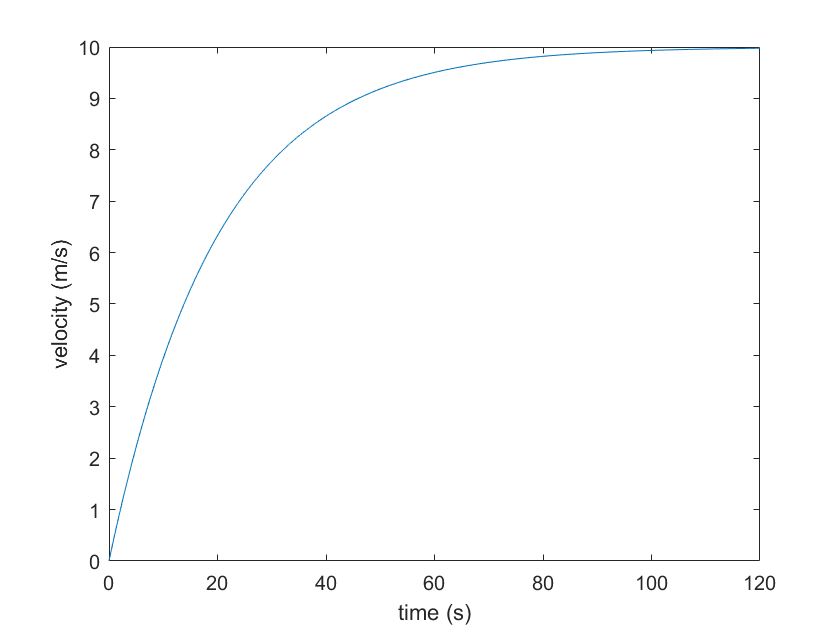

%Question 12

m = 1000;
b12 = 50;
u = 500;
step_size = 0.1;
int_interval = 120/step_size;%integrate over intervals of 100ms

V = zeros(1,int_interval+1);
for i = 1:int_interval
    V(i+1) = V(i)+step_size*((u-b12*V(i))/m); %integrate
end
V;
figure()
plot(0:step_size:120, V)
xlabel('time (s)')
ylabel('velocity (m/s)')

%Question 9 function

function [dMiss] = cannonBall(xT,yT, t, vx, vy)
g = 9.81;

xMiss = vx*t - xT;
yMiss = vy*t - 0.5*g*t^2 - yT;
dMiss = sqrt(xMiss.^2 + yMiss.^2);
end